# Distribution of swimming speeds

This live MATLAB script plots histograms of average swimming speeds, defined as the swimmer displacement over a beat period divided by the period.

## Data for individual sperm

For which sperm do you wish to display the beat period, flagellum length, and MDC? 

[Select an integer from 1 to 216]

% NOTE: This MATLAB live script contains a mixture of code written by
% -- the authors of Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. 
% (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms 
% of bovine spermatozoa. R. Soc. Open Sci. 7: 200769
% -- the members of Cambridge InfertiliTEAM for inFer GW4 network Hackathon
load swimmingspeeds.mat
load masks.mat
bleb_speeds = B_speeds(find(bleb_mask == 1) - 79);
unbleb_speeds = B_speeds(find(unbleb_mask == 1) - 79);

spermid = 3;

if spermid <= 79
    vbar = A_speeds(spermid);
else
    vbar = B_speeds(spermid - 1);
end

disp(['average swimming speed = ' num2str(vbar) ' μm^{-1}'])

average swimming speed = 8.4544 μm^{-1}


## Histogram of swimming speeds

Which sample do you wish to plot?

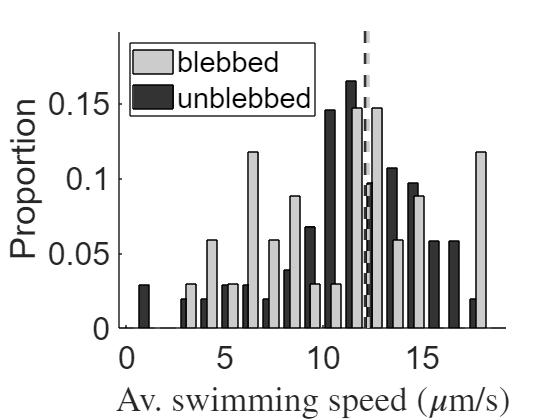

KS p value: 0.1947


sample = 6;

if sample == 3

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_speeds,B_speeds]);
maxx = max([A_speeds,B_speeds]);
edges = linspace(0,20,20);
hA = histcounts(A_speeds,edges,'Normalization','probability');
hB = histcounts(B_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])
[h,p] = kstest2(A_speeds,B_speeds);
disp(['KS p value: ',num2str(p)])

elseif sample == 1

figure
hold on
A_col = 0.8;
minx = min([A_speeds]);
maxx = max([A_speeds]);
edges = linspace(0,20,20);
hA = histcounts(A_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_speeds),1,2),[0,max([hA])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample A'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])

elseif sample == 2
%     close all
%     figure
% subplot(3,1,1)
figure
hold on
B_col = 0.2;
minx = min([B_speeds]);
maxx = max([B_speeds]);
edges = linspace(0,20,20);
hB = histcounts(B_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_speeds),1,2),[0,max([hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample B'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])


elseif sample == 6

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_speeds,unbleb_speeds]);
maxx = max([bleb_speeds,unbleb_speeds]);
edges = linspace(0,20,20);
hA = histcounts(bleb_speeds,edges,'Normalization','probability');
hB = histcounts(unbleb_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])
[h,p] = kstest2(bleb_speeds,unbleb_speeds);
disp(['KS p value: ',num2str(p)])

elseif sample == 4

figure
hold on
A_col = 0.8;
minx = min([bleb_speeds]);
maxx = max([bleb_speeds]);
edges = linspace(0,20,20);
hA = histcounts(bleb_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_speeds),1,2),[0,max([hA])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'blebbed'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])

elseif sample == 5

figure
hold on
B_col = 0.2;
minx = min([unbleb_speeds]);
maxx = max([unbleb_speeds]);
edges = linspace(0,20,20);
hB = histcounts(unbleb_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_speeds),1,2),[0,max([hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'unblebbed'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])
end